% Designing a 1st order IIR low-pass filter
fs = 10; % Sampling frequency (Hz), based on 100ms delay
fc = 0.3; % Cutoff frequency (Hz)
order = 10; % 1st order filter

% Design the filter using butterworth
[b, a] = butter(order, fc/(fs/2), 'low');

% Display coefficients
disp('Numerator coefficients (b):');

Numerator coefficients (b):


disp(b);

   1.0e-08 *

    0.0031    0.0311    0.1402    0.3738    0.6541    0.7849    0.6541    0.3738    0.1402    0.0311    0.0031



disp('Denominator coefficients (a):');

Denominator coefficients (a):


disp(a);

    1.0000   -8.7952   34.8750  -82.0959  127.0429 -135.0355   99.8351  -50.6918   16.9167   -3.3503    0.2990



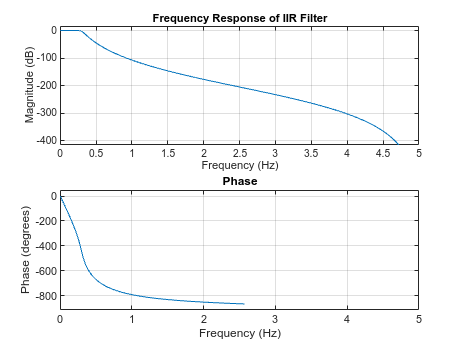


% Optional: Plot frequency response
figure;
freqz(b, a, 512, fs);
title('Frequency Response of IIR Filter');
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');

b

b = 1.0e-08 *

    0.0031    0.0311    0.1402    0.3738    0.6541    0.7849    0.6541    0.3738    0.1402    0.0311    0.0031


a

a =     1.0000   -8.7952   34.8750  -82.0959  127.0429 -135.0355   99.8351  -50.6918   16.9167   -3.3503    0.2990


% Designing an FIR low-pass filter
fs = 10; % Sampling frequency (Hz), based on 100ms delay
fc = 0.3; % Cutoff frequency (Hz)
order = 20; % Filter order (number of taps - 1)

% Normalized cutoff frequency for fir1 (fc/(fs/2))
Wn = fc/(fs/2);

% Design the FIR filter using fir1 (creates a low-pass filter)
b = fir1(order, Wn, 'low');

% For FIR, denominator coefficients (a) are just [1] since there's no feedback
a = [1];

% Display coefficients
disp('Numerator coefficients (b):');

Numerator coefficients (b):


disp(b);

    0.0041    0.0061    0.0112    0.0200    0.0322    0.0469    0.0627    0.0777    0.0901    0.0983    0.1012    0.0983    0.0901    0.0777    0.0627    0.0469    0.0322    0.0200    0.0112    0.0061    0.0041



disp('Denominator coefficients (a):');

Denominator coefficients (a):


disp(a);

     1



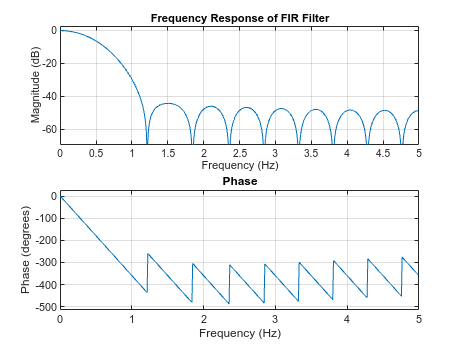


% Optional: Plot frequency response
figure;
freqz(b, a, 512, fs);
title('Frequency Response of FIR Filter');
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');